% -----------------------------------------
% ICE Interpolation
% LiXin
% 2022/3/18
% -----------------------------------------

Problem 1

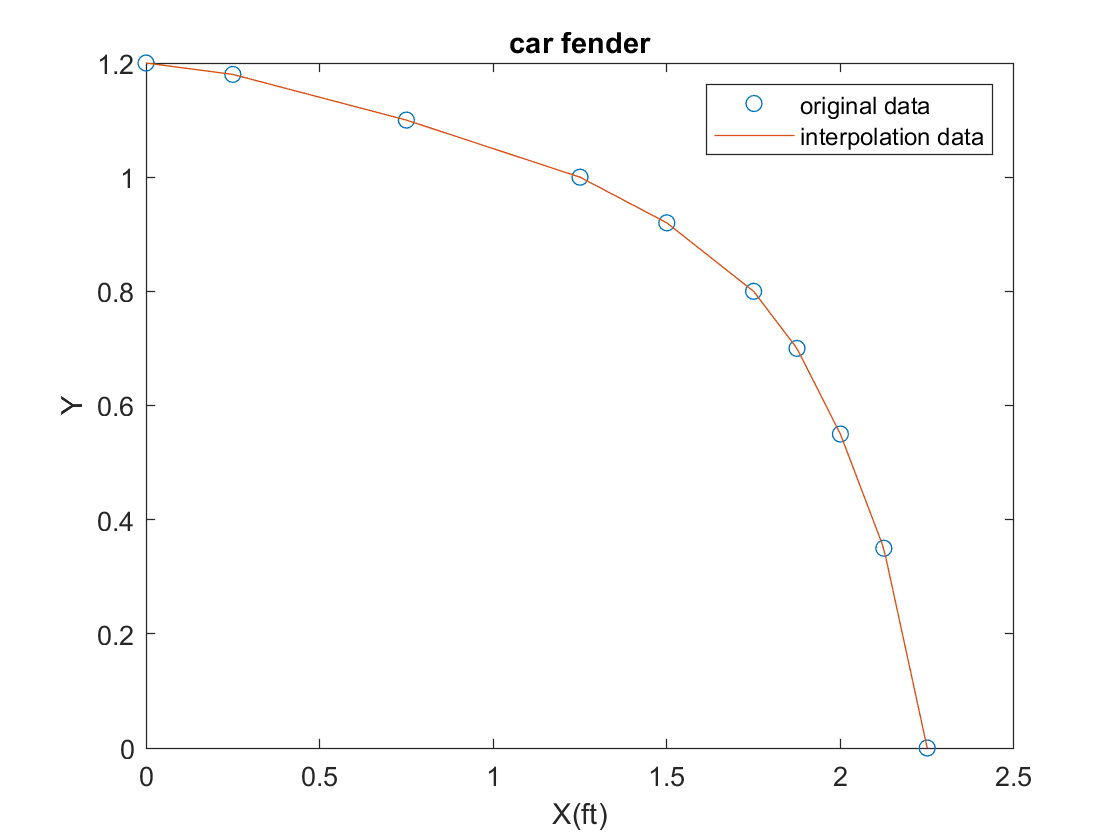

clear all; close all; clc;
X=[0 0.25 0.75 1.25 1.5 1.75 1.875 2 2.125 2.25];
Y=[1.2 1.18 1.1 1 0.92 0.8 0.7 0.55 0.35 0];
plot(X, Y, 'o')
% use interpolation to calculate the entire fender
wq=0:0.01:2.25;
res=interp1(X,Y,wq);
hold on
plot(wq,res)
xlabel('X(ft)'), ylabel('Y'), title('car fender')
legend('original data', 'interpolation data')

Problem 2

clear all; close all; clc;
T=[0 8 16 24 32 40];
o=[14.621 11.843 9.870 8.418 7.305 6.413];

linear interpolation

o27=interp1(T, o, 27, "linear");
fprintf("linear interpolation: %f",o27)

linear interpolation: 8.000625

Newton's interpolating polynomial

pick values T=16~32, using two order polynomial interpolation

p=polyfit(T(1,3:5), o(1,3:5),2);
o27=polyval(p,27);
fprintf("Newton's interpolating second-order: %f", o27);

Newton's interpolating second-order: 7.960898

pick values T=24~40, using two order polynomial interpolation

p=polyfit(T(1,4:6), o(1,4:6),2);
o27=polyval(p,27);
fprintf("Newton's interpolating second-order: %f (the best estimation)", o27);

Newton's interpolating second-order: 7.974727 (the best estimation)

pick values T=16~40, using three order polynomial interpolation

p=polyfit(T(1,3:6), o(1,3:6),3);
o27=polyval(p,27);
fprintf("Newton's interpolating third-order: %f", o27)

Newton's interpolating third-order: 7.967236

pick values T=8~40, using four order polynomial interpolation

p=polyfit(T(1,2:6), o(1,2:6),4);
o27=polyval(p,27);
fprintf("Newton's interpolating fourth-order: %f", o27)

Newton's interpolating fourth-order: 7.968633

pick values T=0~40, using fifth order polynomial interpolation

p=polyfit(T(1,1:6), o(1,1:6),5);
o27=polyval(p,27);
fprintf("Newton's interpolating fourth-order: %f", o27)

Newton's interpolating fourth-order: 7.968239

cubic splines

o27=interp1(T, o, 27, "cubic");
fprintf("cubic splines: %f", o27)

cubic splines: 7.966084

Problem 3

clear all; close all; clc;
t=linspace(0, 2*pi, 8);
ft=sin(t).^2;
x=0:0.01:2*pi;

(a) seventh-order interpolation

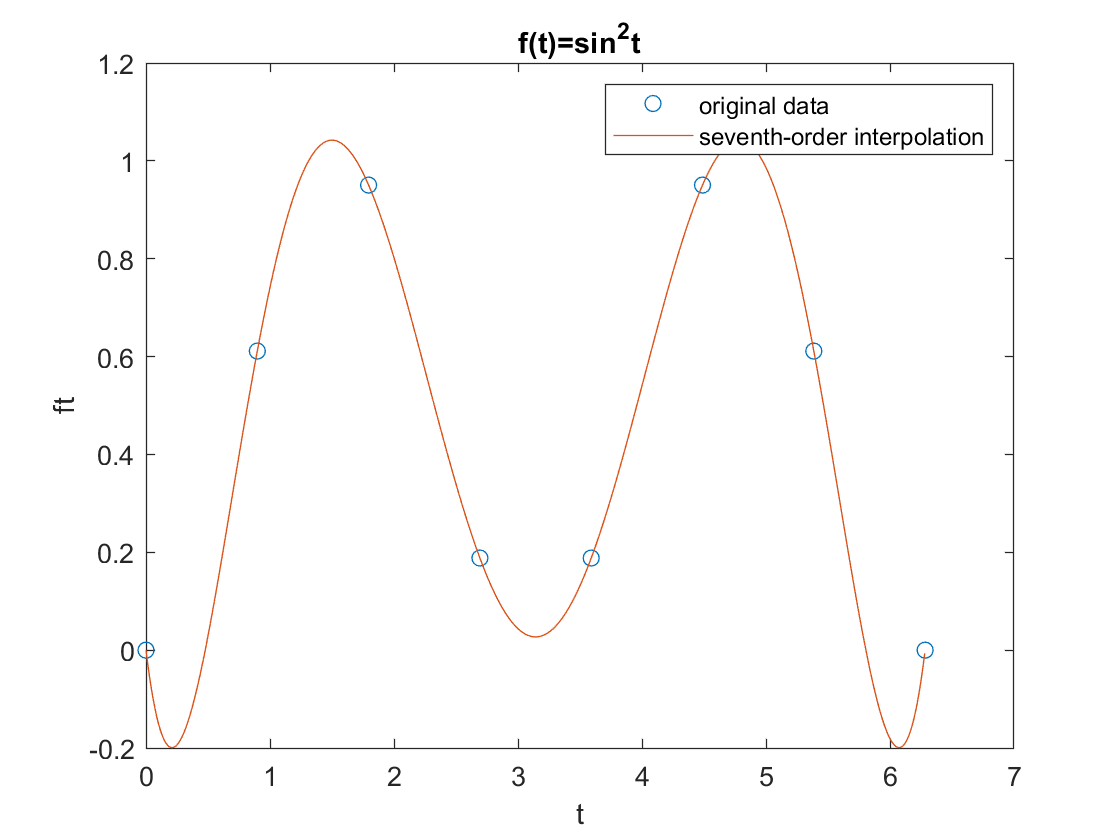

p=polyfit(t,ft,7);
y=polyval(p,x);
plot(t,ft,'o')
xlabel('t'),ylabel('ft'),title('f(t)=sin^2t')
hold on
plot(x,y)
hold off
legend('original data', 'seventh-order interpolation')

(b) cubic spline

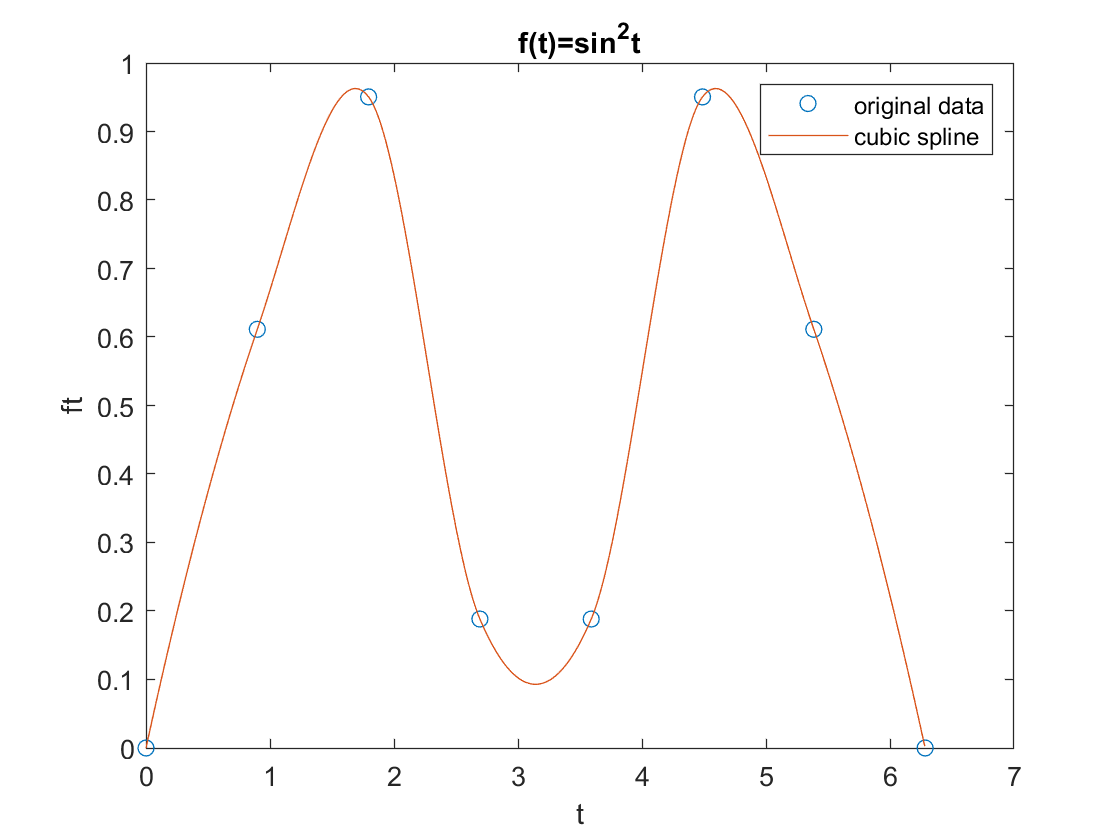

y=interp1(t,ft,x,"cubic");
plot(t,ft,'o')
xlabel('t'),ylabel('ft'),title('f(t)=sin^2t')
hold on
plot(x,y)
legend('original data', 'cubic spline')